Example of UTS*Area load cases 

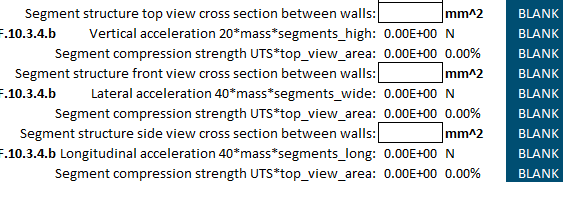

Battery Coverved Volume dimensions(what area the casing must enclose)

https://enepaq.com/wp-content/uploads/2023/09/VTC6-Sony-Murata-Li-ion-Battery-Module-With-Temperature-Sensor-Datasheet-Tesla-Battery-Sponsorship-Formula-SAE-Electric-Formula-Student-Battery-Pack.pdf


EneModWidth = 20.3/1000;%width(ex:65mm(cell)+module sides)
EneSegHeight =  105.6/1000;%height(m)
EneSegDepth = 69.5/1000;
ModuleWeight = 278/1000;%weight in kg
SegmentCasingHeight = 0.10555;%m

EneSegmentDepth = 6*EneSegDepth/1000%num modules*moduleDepth*mmtoinches

EneSegmentDepth = 4.1700e-04

EneSegmentWidth = EneModWidth * 4

EneSegmentWidth = 0.0812

SegmentWeight = ModuleWeight*23;
CasingThickness = 1/8*25.4/1000;

TopCrossSecArea = EneSegmentDepth*CasingThickness*2

TopCrossSecArea = 2.6480e-06

TopCrossSecForce = SegmentWeight*20*9.8%in newtons

TopCrossSecForce = 1.2532e+03

TopStress = TopCrossSecForce/TopCrossSecArea

TopStress = 4.7328e+08


WidthCrossSecArea = EneSegmentDepth*CasingThickness*2

WidthCrossSecArea = 2.6480e-06

WidthCrossSecForce = 6*SegmentWeight*40*9.8%in newtons

WidthCrossSecForce = 1.5039e+04

WidthStress = WidthCrossSecForce/WidthCrossSecArea

WidthStress = 5.6794e+09



DepthCrossSecArea = EneSegmentWidth*CasingThickness*2 + EneSegHeight*CasingThickness*2

DepthCrossSecArea = 0.0012

DepthCrossSecForce = SegmentWeight * 40 * 9.8;
DepthStress = DepthCrossSecForce/DepthCrossSecArea

DepthStress = 2.1130e+06

Bolt calculations

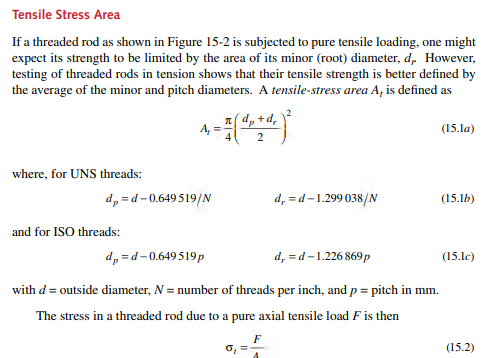

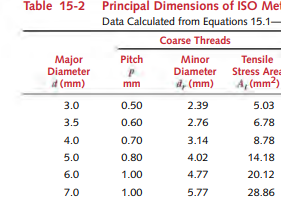

 dia = 6;
 pitch = 1;
diaPitch = dia - 0.649519*pitch;%mm 
diaRoot = dia - 1.226869*pitch ;%mm
AreaBoltTensile = pi/4*((diaPitch+diaRoot)/2)^2;%in mm^2
ABTMeters = AreaBoltTensile/1000000

ABTMeters = 2.0123e-05


exampleGr5Tensile = 827370875%pa 

exampleGr5Tensile = 827370875

MaxForce = exampleGr5Tensile*ABTMeters %newtons

MaxForce = 1.6649e+04

Tear out calcs

[https://laminatedplastics.com/g-10.pdf](https://laminatedplastics.com/g-10.pdf) 

strength values from here

psiTopPascal = 6894.76;
garoliteStrength = 38000*psiTopPascal;
garoliteThickness = 6.35/1000;
BoltDistanceFromEdge = 8/1000;%mm  realistic distance from edge

maxTearoutForce = BoltDistanceFromEdge*garoliteThickness*garoliteStrength

maxTearoutForce = 1.3310e+04

fr4BondStrength = 2200*psiTopPascal

fr4BondStrength = 15168472

MinFlangeBondArea = DepthCrossSecForce/fr4BondStrength

MinFlangeBondArea = 1.6524e-04

FlangeBondSF = 1;%when one side goes into tension the other should go into compression. 
MinAdhesivedAreaForFlange = MinFlangeBondArea * FlangeBondSF 

MinAdhesivedAreaForFlange = 1.6524e-04


DepthRestrictingBondArea = garoliteThickness * 80/1000

DepthRestrictingBondArea = 5.0800e-04

SideBondArea = 0.02* garoliteThickness*2;

SideBondArea = 2.5400e-04